# Experiments with Travelling Salesman Problem

clear;
cities = importdata('cities.csv');
nGenes = length(cities.data);

## Experiment 1

Mutation: Use random swapping of cities when mutating Recombination: Use one point crossover

p(1).maxGenerations = 1000;
p(1).populationSize = 20;
p(1).crossoverRate = 0.9;
p(1).mutationRate = 1/nGenes;
p(1).nSpecies = p(1).populationSize/4;
p(1).useSpeciation = true;
p(1).useRandomMutation = true;
p(1).useOnePointCrossover = true;
p(1).cities = cities;
name{1} = 'speciation random one point';

## Experiment 2

Mutation: Swap neighboured cities only when mutating Recombination: Use one point crossover Speciation: kMeans

p(2) = p(1);
p(2).useRandomMutation = false;
p(2).useOnePointCrossover = true;
name{2} = 'speciation neighbour one point';

## Experiment 3

Mutation: Use random swapping of cities when mutating Recombination: Use two point crossover Speciation: kMeans

p(3) = p(1);
p(3).useRandomMutation = true;
p(3).useOnePointCrossover = false;
name{3} = 'speciation random two point';

## Experiment 4

Mutation: Swap neighboured cities only when mutating Recombination: Use two point crossover Speciation: kMeans

p(4) = p(1);
p(4).useRandomMutation = false;
p(4).useOnePointCrossover = false;
name{4} = 'speciation neighbour two point';

## Experiment 5

Mutation: Swap neighboured cities only when mutating Recombination: Use one point crossover Speciation: none

p(5) = p(1);
p(5).useRandomMutation = false;
p(5).useOnePointCrossover = true;
p(5).useSpeciation = false;
name{5} = 'neighbour one point';

## Experiment 6

Mutation: Use random swapping of cities when mutating Recombination: Use two point crossover Speciation: none

p(6) = p(1);
p(6).useRandomMutation = true;
p(6).useOnePointCrossover = false;
p(6).useSpeciation = false;
name{6} = 'random two point';

## Experiment 7

Mutation: Swap neighboured cities only when mutating Recombination: Use two point crossover Speciation: none

p(7) = p(1);
p(7).useRandomMutation = false;
p(7).useOnePointCrossover = false;
p(7).useSpeciation = false;
name{7} = 'neighbour two point';

## Experiment 8

Mutation: Swap neighboured cities only when mutating Recombination: Use two point crossover Speciation: none

p(8) = p(1);
p(8).useRandomMutation = false;
p(8).useOnePointCrossover = false;
p(8).useSpeciation = false;
name{8} = 'neighbour two point';

## Run Experiments

tic;
for i=1:8
    clear bestFitness medianFitness;
    parfor run = 1:100
        r(run) = doTsp(p(i));
        bestFitness(run,:) = r(run).bestFitness;
        medianFitness(run,:) = r(run).medianFitness;
    end
    p(i).medianBestFitness = median(bestFitness,1);
    p(i).medianMedianFitness = median(medianFitness,1);
end
toc;

Elapsed time is 362.443675 seconds.


## Plot Routes

for i=1:8 figure(i);clf;hold on; plotRoute(cities, r(i)); title(name{i}); end

## Plot Fitnesses

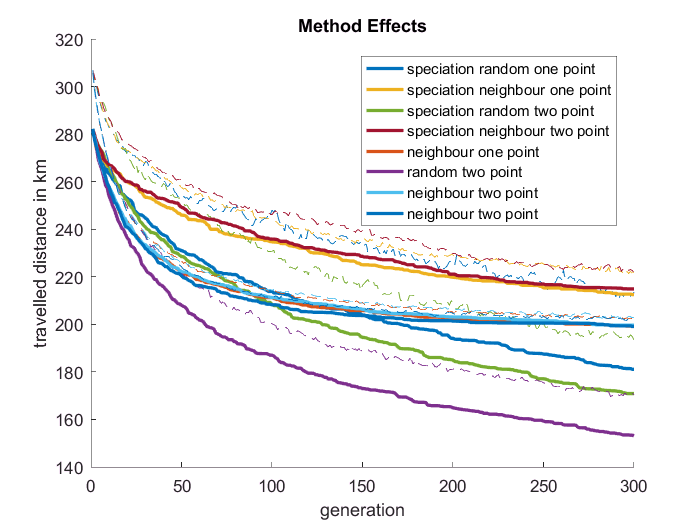

figure(1);clf;hold on;
for i=1:8
    lineHandles(i) = plot(-1*p(i).medianBestFitness,'-','LineWidth',2);
    plot(-1*p(i).medianMedianFitness,'--','Color',get(lineHandles(i),'Color'));
end
ylabel('travelled distance in km');
xlabel('generation');
legend(lineHandles,name,'Location','NorthEast');
title('Method Effects');